**Sampling and recovery using different orthonormal basis functions**

Lets assume  two given priodic signals: $f\left(t\right)$ and $g\left(t\right)$:


$$\textrm{𝑓}\left(t\right)=4\cos \left(4\frac{\textrm{𝜋t}}{T}\right)+\sin \left(\frac{10\textrm{𝜋𝑡}}{T}\right)$$



$$\mathrm{𝑔}\left(t\right)=2\mathrm{𝑠𝑖𝑔𝑛}\left(\mathrm{sin}\left(\frac{6\mathrm{𝜋}}{T}t\right)\right)-4\mathrm{𝑠𝑖𝑔𝑛}\left(\mathrm{sin}\left(\frac{4\mathrm{𝜋𝑡}}{T}\right)\right)$$


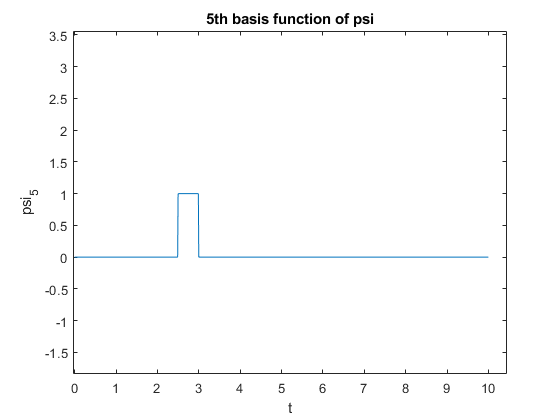

T = 10;
t = 0:1/100:10;


g = @(t) 2*sign(sin(6*pi*t/T)) -4*sign(sin(4*pi*t/T));

f = @(t) 4*cos(4*pi*t/T) + sin(10*pi*t/T);

n = -20:20;
phi =  exp(1i*2*pi*(t.').*n/T);
f_phi = @(t) exp(1i*2*pi*(t.').*n/T);


n = 0:19;
psi = rectpuls(t.'/(T/20) -(n+0.5),2*(T/20));
f_psi =@(n,t) rectpuls(t.'/(T/20) -(n+0.5),2*(T/20));

plot(t,f_psi(5,t)); title("5th basis function of psi") ;xlabel("t"); ylabel('psi_5')

xlim([-0.04 10.45])
ylim([-1.84 3.56])

nowthat everything is set up, it is time to define our function that will take in the basis functions $\psi_n \left(t\right)$ or perheps $\phi_n \left(t\right)$ and in addition a signal $g\left(t\right)$ and output $a_n$, the projection coefficients. such that:


$$c_n =\frac{\int_0^T x\left(t\right)\phi_n^* \left(t\right)\textrm{dt}}{\left|\right|\phi_n \left(t\right)\left|\right|}$$


so we will:

1.calculate the norm, squared.

2.calculate the projection.

3.devide them for each n, to get the n'th coefficient.

**the function is declared at the **end **of the document, and is as follows:

% function [a_hat] = Projection_coef(x,PSI,T)
% %INPUT: x -continuos time x(t) values
% %       PSI - a matrix wit basis functions
% %       T period duration
% %       
%     PSI_CONJ = conj(PSI);
%     norm = trapz(abs(PSI.^2));
%     proj = trapz(x.'.*PSI_CONJ);
%     a_hat = proj/norm;
% end


_____________________________________________________________

let us calculate the coefficients $c_n$ for $\textrm{𝑓}\left(t\right)$ using $\phi_n \left(t\right)$ basis functins.

a quick reminder:


$$\textrm{𝑓}\left(t\right)=4\cos \left(4\frac{\textrm{𝜋t}}{T}\right)+\sin \left(\frac{10\textrm{𝜋𝑡}}{T}\right)$$


cn_of_f_using_phi = Projection_coef(f(t), phi , T);
TAB =table(cn_of_f_using_phi)

TAB = table
    cn_of_f_using_phi
    _________________

      [1×41 double]  


let's plot it just to understand what we see:

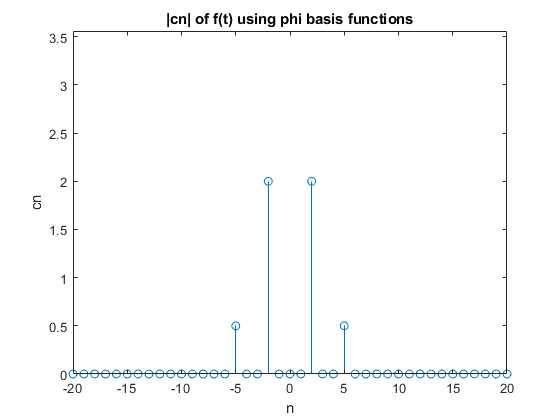

stem(-20:20,abs(cn_of_f_using_phi) ); title('|cn| of f(t) using phi basis functions'),xlabel('n');ylabel('cn')
ylim([0 3.56])

explaination:

we got exactly what we shuld have expected. f consists of 2 frequancies exactly (of sine and cosine) which means 4 spikes total, conjugates inclouded. ($\left.\pm \omega_a \;,\pm i\cdot \omega_b \right)$ 

now we shall move to calculate the coefficients $c_n$ for $\textrm{𝑓}\left(t\right)$ using $\psi_n \left(t\right)$ basis functins.

cn_of_f_using_psi = Projection_coef(f(t), psi , T);
TAB =table(cn_of_f_using_psi);


again plotting will help us a great del to understand the table:

stem(0:19,abs(cn_of_f_using_psi) ); title('|cn| of f(t) using psi basis functions'),xlabel('n');ylabel('cn')
ylim([0 5])

explaination:

to understand the coefficients graph shape we shuld take a look at the signal:

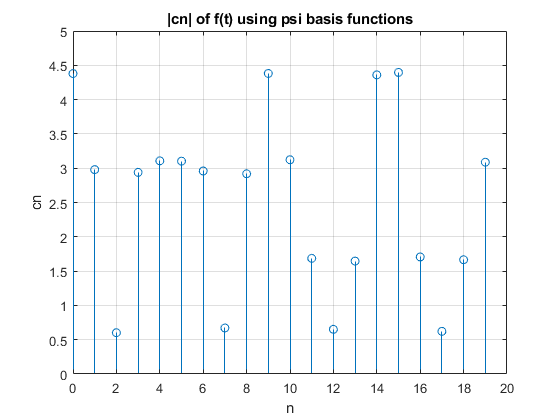

grid on;

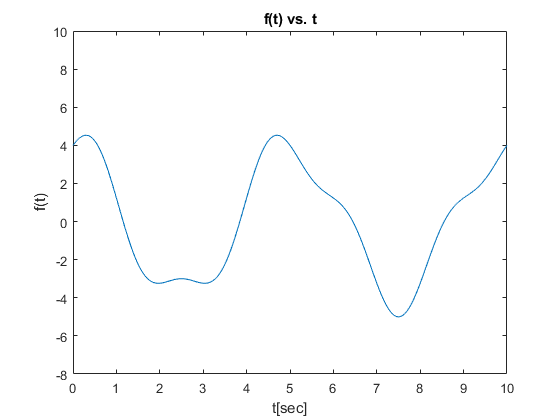

plot( t,f(t)); title ('f(t) vs. t') ; xlabel('t[sec]');ylabel('f(t)')
ylim([-8 10])

 the projection is exactly proportional to the integral of $\textrm{𝑓}\left(t\right)$ in the respective 0.05T section! so when we look at each $c_n$ we see a normalized sum ( average ) of the $\textrm{𝑓}\left(t\right)$ signal at each time section respectively.

________________________   $g\left(t\right)$    ____________________________

now is the time to calculate the coefficients $c_n$ for $g\left(t\right)$ using $\phi_n \left(t\right)$ basis functins.

we defined:


$$\textrm{𝑔}\left(t\right)=2\textrm{𝑠𝑖𝑔𝑛}\left(\sin \left(\frac{6\textrm{𝜋}}{T}t\right)\right)-4\textrm{𝑠𝑖𝑔𝑛}\left(\sin \left(\frac{4\textrm{𝜋𝑡}}{T}\right)\right)$$


cn_of_g_using_phi = Projection_coef(g(t), phi , T);
TAB =table(cn_of_g_using_phi)

TAB = table
    cn_of_g_using_phi
    _________________

      [1×41 double]  


let's plot it just to understand what we see:

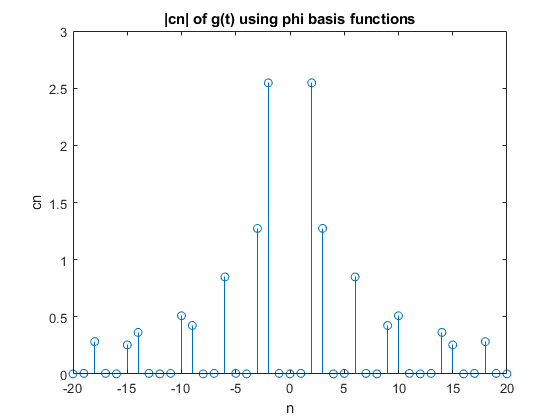

stem(-20:20,abs(cn_of_g_using_phi) ); title('|cn| of g(t) using phi basis functions'),xlabel('n');ylabel('cn')

explaination:

once again we got exactly what we deserve. this time g consists of infinity frequancies (althogh it seems to be but an innocent trig function)  because of the underivable sign function. later we will plot the signal and see that it is not even continuos, meaning, from intro to fourier analysis, that it is the reason to the "ripples"  in the coefficients.

now we shall move to calculate the coefficients $c_n$ for $g\left(t\right)$ using $\psi_n \left(t\right)$ basis functins.

cn_of_g_using_psi = Projection_coef(g(t), psi , T);
TAB =table(cn_of_g_using_psi);


again plotting will help us a great del to understand the table:

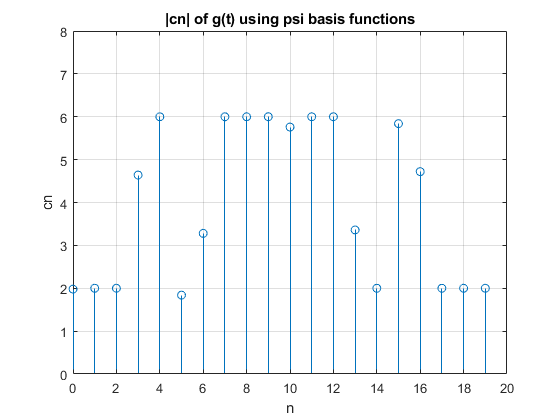

stem(0:19,abs(cn_of_g_using_psi) ); title('|cn| of g(t) using psi basis functions'),xlabel('n');ylabel('cn')
ylim([0 8])
grid on

explaination:

like before , to understand the coefficients graph shape we shuld take a look at the signal:

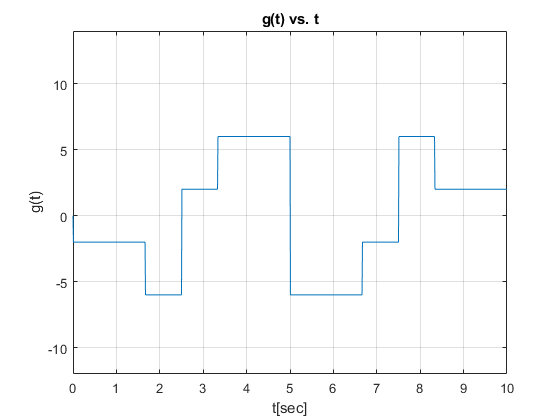


plot( t,g(t)); title ('g(t) vs. t') ; xlabel('t[sec]');ylabel('g(t)')
ylim([-12 14])
grid on;

once again, we get what we deserve: the projection is exactly proportional to the integral of $g\left(t\right)$ in the respective 0.05T section! so when we look at each $c_n$ we see a normalized sum ( average ) of the $g\left(t\right)$ signal at each time section respectively.

to recover the original signals we will use the recover formula:


$$\textrm{𝑥̂}\left(\textrm{𝑡}\right)=∑{\mathrm{c}}_n \phi_n \left(\textrm{𝑡}\right)$$


here we calculate-


$$\hat{f} \left(t\right)=\sum_{n=-20}^{20} {\mathrm{c}}_n \phi_n \left(\textrm{𝑡}\right)$$


f_hat = sum((cn_of_f_using_phi.*phi).');
plot(t,f_hat); title('f(t) recoverd using phi basis functions');xlabel('t[sec]');ylabel('f(t) recoverd sinal')

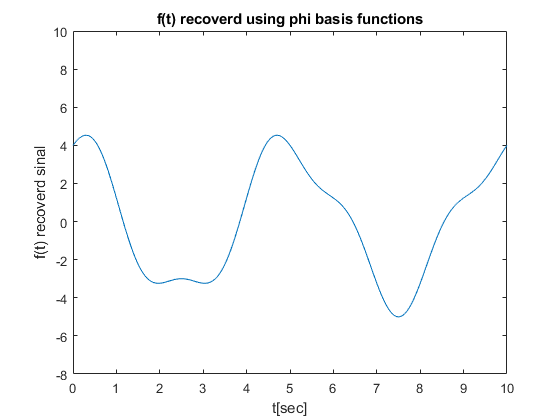

ylim([-8 10])

looking good so far. out ofcuriosity, we must check if the recovery is perfect.

plot(t,f_hat, t,f(t),'--',"linewidth",2); title('f(t) recoverd using phi basis functions');xlabel('t[sec]');ylabel('f(t) recoverd sinal') ;legend("f_hat","f(t)")

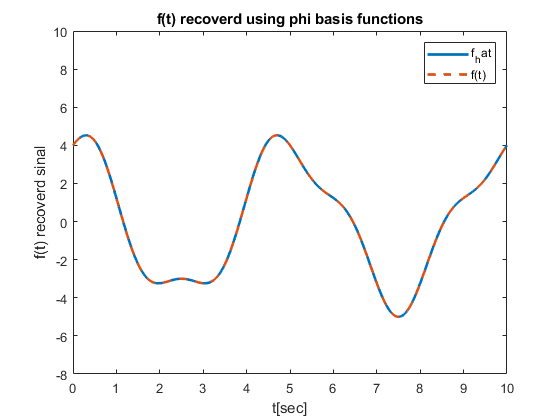

ylim([-8 10])

the recovery is perfect. this is obvious, it happens because $\left\lbrace \phi_n \left(\textrm{𝑡}\right)\right\rbrace$ spans the hibertspace to which f(t) belongs.

we want to also calculate-


$$\hat{f} \left(t\right)=\sum_{n=-20}^{20} {\mathrm{c}}_n \psi_n \left(\textrm{𝑡}\right)$$


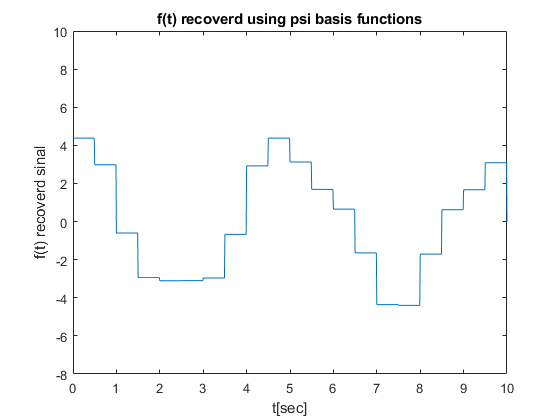

f_hat_psi = sum((cn_of_f_using_psi.*psi).');
plot(t,f_hat_psi); title('f(t) recoverd using psi basis functions');xlabel('t[sec]');ylabel('f(t) recoverd sinal')
ylim([-8 10])

looking simmilar also but surely, the recovery is **not** perfect.

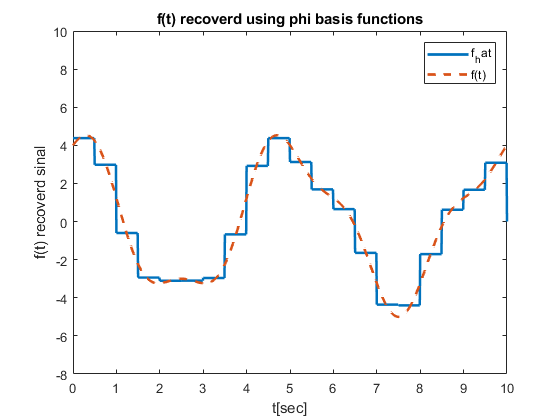

plot(t,f_hat_psi, t,f(t),'--',"linewidth",2); title('f(t) recoverd using phi basis functions');xlabel('t[sec]');ylabel('f(t) recoverd sinal') ;legend("f_hat","f(t)")
ylim([-8 10])

this is because of curse, $\left.{\left\lbrace \psi \right.}_n \left(\textrm{𝑡}\right)\right\rbrace$ does not span the space in which f  exists, and thus a perfect recovery will be impossible. more precision can be achived using a larger number of (narrower pulse) basis functions.

________________________$g\left(t\right)$____________________________

now we calculate the same for g:


$$\hat{g} \left(t\right)=\sum_{n=-20}^{20} {\mathrm{c}}_n \phi_n \left(\textrm{𝑡}\right)$$


g_hat = sum((cn_of_g_using_phi.*phi).');
plot(t,g_hat); title('g(t) recoverd using phi basis functions');xlabel('t[sec]');ylabel('g(t) recoverd sinal')

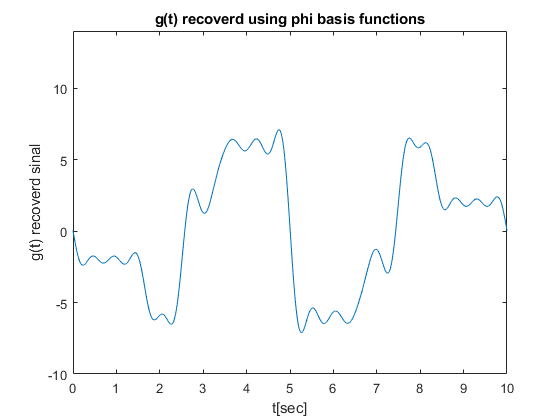

ylim([-10 14])

this resembles the shape but this is not  a good recovery. let;s compare it with g(t):

plot(t,g_hat, t,g(t),'--',"linewidth",2); title('g(t) recoverd using phi basis functions');xlabel('t[sec]');ylabel('g(t) recoverd sinal') ;legend("f_hat","f(t)")

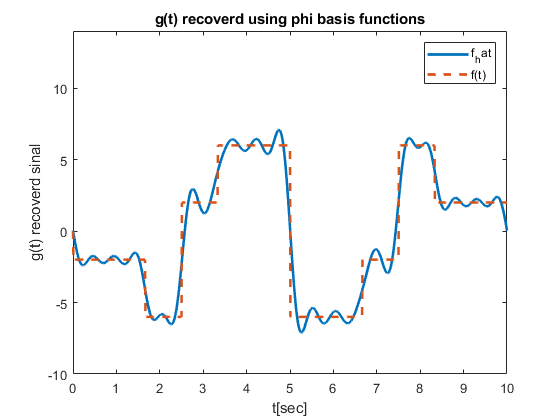

ylim([-10 14])

this is because again, $\left.{\left\lbrace \phi \right.}_n \left(\textrm{𝑡}\right)\right\rbrace$ does not span the space in which g  exists.

we want to also calculate-


$$\hat{g} \left(t\right)=\sum_{n=0}^{20} {\mathrm{c}}_n \psi_n \left(\textrm{𝑡}\right)$$


g_hat_psi = sum((cn_of_g_using_psi.*psi).');
plot(t,g_hat); title('g(t) recoverd using psi basis functions');xlabel('t[sec]');ylabel('g(t) recoverd sinal')

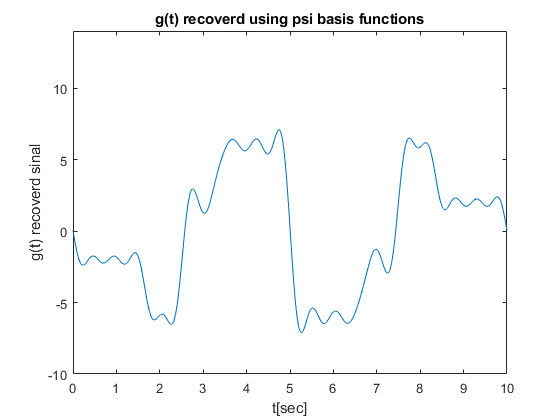

ylim([-10 14])

looking simmilar also but again, the recovery is **not** perfect.

a perfect recovery won't be possible, and as discussed, more precision will require more basis functions, as close as possible to infinity.

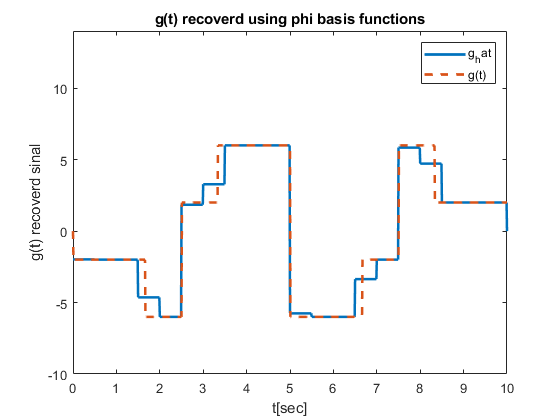

plot(t,g_hat_psi, t,g(t),'--',"linewidth",2); title('g(t) recoverd using phi basis functions');xlabel('t[sec]');ylabel('g(t) recoverd sinal') ;legend("g_hat","g(t)")
ylim([-10 14])

this is because of curse, $\left.{\left\lbrace \psi \right.}_n \left(\textrm{𝑡}\right)\right\rbrace$ does not span the space in which g  exists, they may resemble eachothers characteristics, but no series of$\alpha_n$ in the complex plane gives us   $g\left(t\right)=\sum_{n=0}^{20} \alpha_n \psi_n \left(\textrm{𝑡}\right)$

so a perfect recover wouldn't be possible. it may be perfect for other $\psi_n \left(\textrm{𝑡}\right)$ choises though, perheps more pulses, wth narrower dutycycles.(s.t at least every rise and falls of g will aline with one rise and fall respectively of $\psi_n \left(\textrm{𝑡}\right)$)

function [a_hat] = Projection_coef(x,PSI,T)
%INPUT: x -continuos time x(t) values
%       PSI - a matrix wit basis functions
%       T period duration
%       
    PSI_CONJ = conj(PSI);
    norm = trapz(abs(PSI.^2));
    proj = trapz(x.'.*PSI_CONJ);
    a_hat = proj./norm;
end